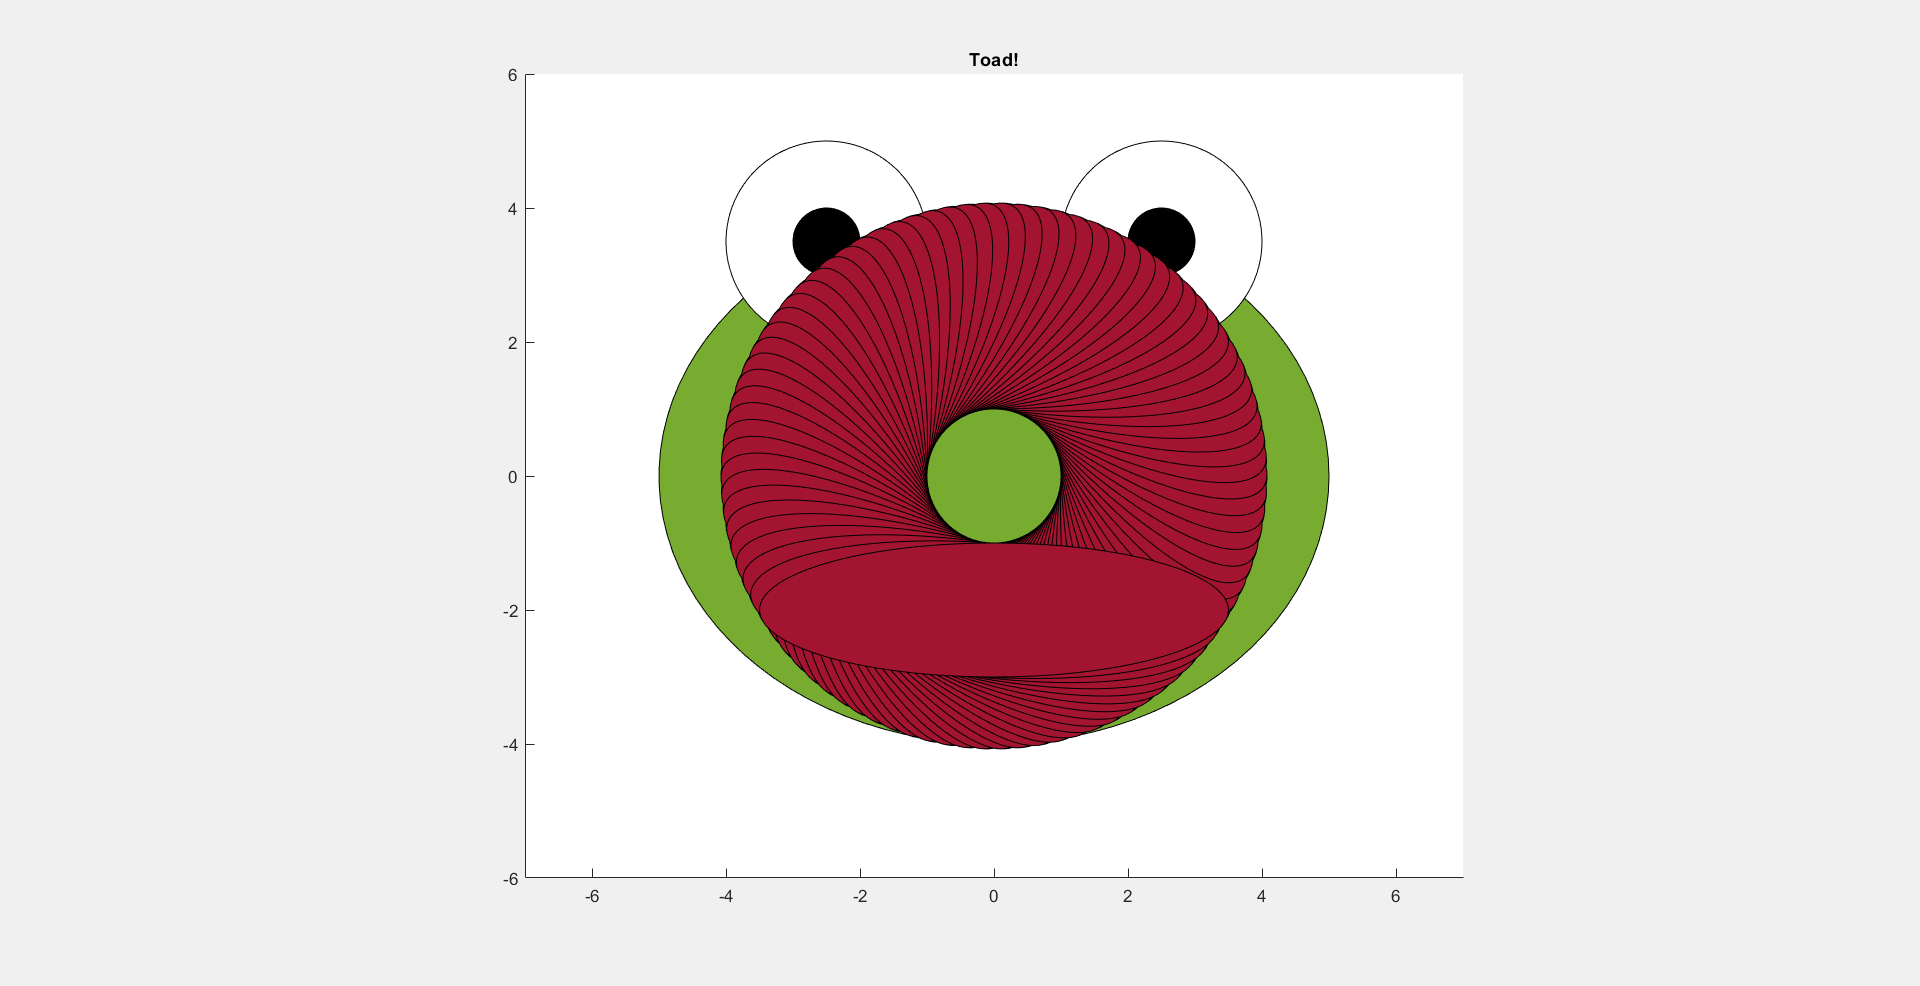

clc;
clear;

f = figure('Visible', 'on'); 
hold on;

% Frog head (circle)
t = linspace(0, 2*pi, 100); 
x_head = 5 * cos(t);         
y_head = 4 * sin(t);         

% eyes and pupils
x_eye_left = 1.5 * cos(t) - 2.5;  
y_eye_left = 1.5 * sin(t) + 3.5;  
x_eye_right = 1.5 * cos(t) + 2.5;  
y_eye_right = 1.5 * sin(t) + 3.5;  
x_pupil_left = 0.5 * cos(t) - 2.5;  
y_pupil_left = 0.5 * sin(t) + 3.5;
x_pupil_right = 0.5 * cos(t) + 2.5;  
y_pupil_right = 0.5 * sin(t) + 3.5;

% blush
x_blush_left = 0.7 * cos(t) - 3;  
y_blush_left = 0.7 * sin(t) - 1.5;
x_blush_right = 0.7 * cos(t) + 3;  
y_blush_right = 0.7 * sin(t) - 1.5;

% plot
fill(x_head, y_head, [0.4660 0.6740 0.1880]);  
fill(x_eye_left, y_eye_left, [1 1 1]);  
fill(x_eye_right, y_eye_right, [1 1 1]);  
fill(x_pupil_left, y_pupil_left, [0 0 0]);  
fill(x_pupil_right, y_pupil_right, [0 0 0]);  
fill(x_blush_left, y_blush_left, [1 0.6 0.6]);  
fill(x_blush_right, y_blush_right, [1 0.6 0.6]);  

axis equal;
axis([-7 7 -6 6]);
title('Toad!');

pause(3); % 3-second delay

% mouth
for angle = 0:4:360
    % Create rotation matrix
    theta = deg2rad(angle);
    R = [cos(theta) -sin(theta); sin(theta) cos(theta)];
    
    % mouth coordinates
    mouth_coords = [3.5 * cos(t); 1.0 * sin(t) - 2]; % Original mouth coordinates
    rotated_mouth_coords = R * mouth_coords;
    
    % Extract rotated x and y
    x_mouth_rotated = rotated_mouth_coords(1, :);
    y_mouth_rotated = rotated_mouth_coords(2, :);
    
    % Clear the current mouth and plot new mouth
    fill(x_mouth_rotated, y_mouth_rotated, [0.6350 0.0780 0.1840]);
    
    % Pause to create animation effect
    pause(0.05);
end

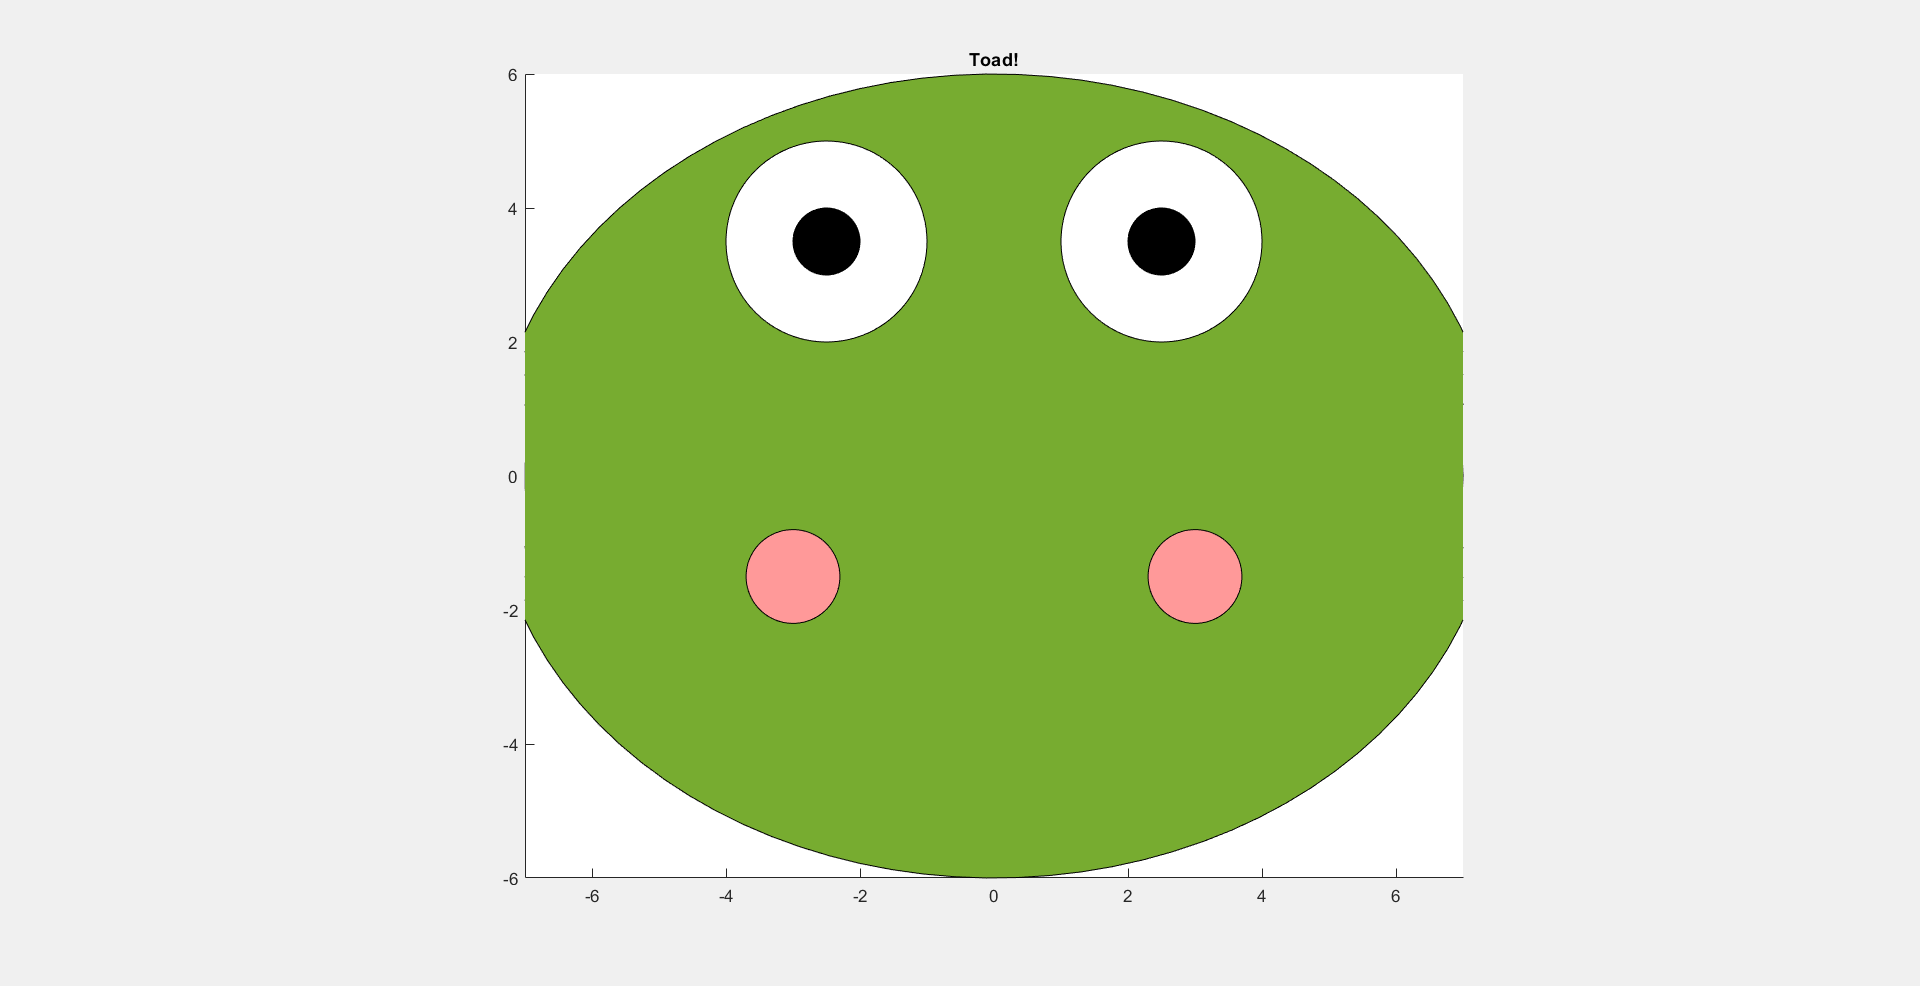


clf;

% Zoom effect on the head only
zoom_duration = 0.5; % Duration for zoom effect
steps = 20; % Number of steps for zooming
scale_factor = 1.5; % Scale factor for zoom

% Zoom in the head
for s = 1:steps
    current_scale = 1 + (scale_factor - 1) * (s / steps);
    
    % Update head positions
    x_head_zoomed = current_scale * x_head;  
    y_head_zoomed = current_scale * y_head;  

    % Clear and redraw the frog with zoomed head
    hold on;  
    fill(x_head_zoomed, y_head_zoomed, [0.4660 0.6740 0.1880]);  
    fill(x_eye_left, y_eye_left, [1 1 1]);  
    fill(x_eye_right, y_eye_right, [1 1 1]);  
    fill(x_pupil_left, y_pupil_left, [0 0 0]);  
    fill(x_pupil_right, y_pupil_right, [0 0 0]);  
    fill(x_blush_left, y_blush_left, [1 0.6 0.6]);  
    fill(x_blush_right, y_blush_right, [1 0.6 0.6]);  

    hold on;

    % Plot settings
    axis equal;
    axis([-7 7 -6 6]);
    title('Toad!');
    
    % Pause for the zoom effect
    pause(zoom_duration / steps);
end

hold on;

% Zoom effect on the eyes, pupils, and blush
% Update head positions
    x_head_zoomed = current_scale * x_head;  
    y_head_zoomed = current_scale * y_head;  

    % Clear and redraw the frog with zoomed head
    hold on;  
    fill(x_head_zoomed, y_head_zoomed, [0.4660 0.6740 0.1880]);  
    fill(x_eye_left, y_eye_left, [1 1 1]);  
    fill(x_eye_right, y_eye_right, [1 1 1]);  
    fill(x_pupil_left, y_pupil_left, [0 0 0]);  
    fill(x_pupil_right, y_pupil_right, [0 0 0]);  
    fill(x_blush_left, y_blush_left, [1 0.6 0.6]);  
    fill(x_blush_right, y_blush_right, [1 0.6 0.6]);  

    hold on;

    % Plot settings
    axis equal;
    axis([-7 7 -6 6]);
    title('Toad!');

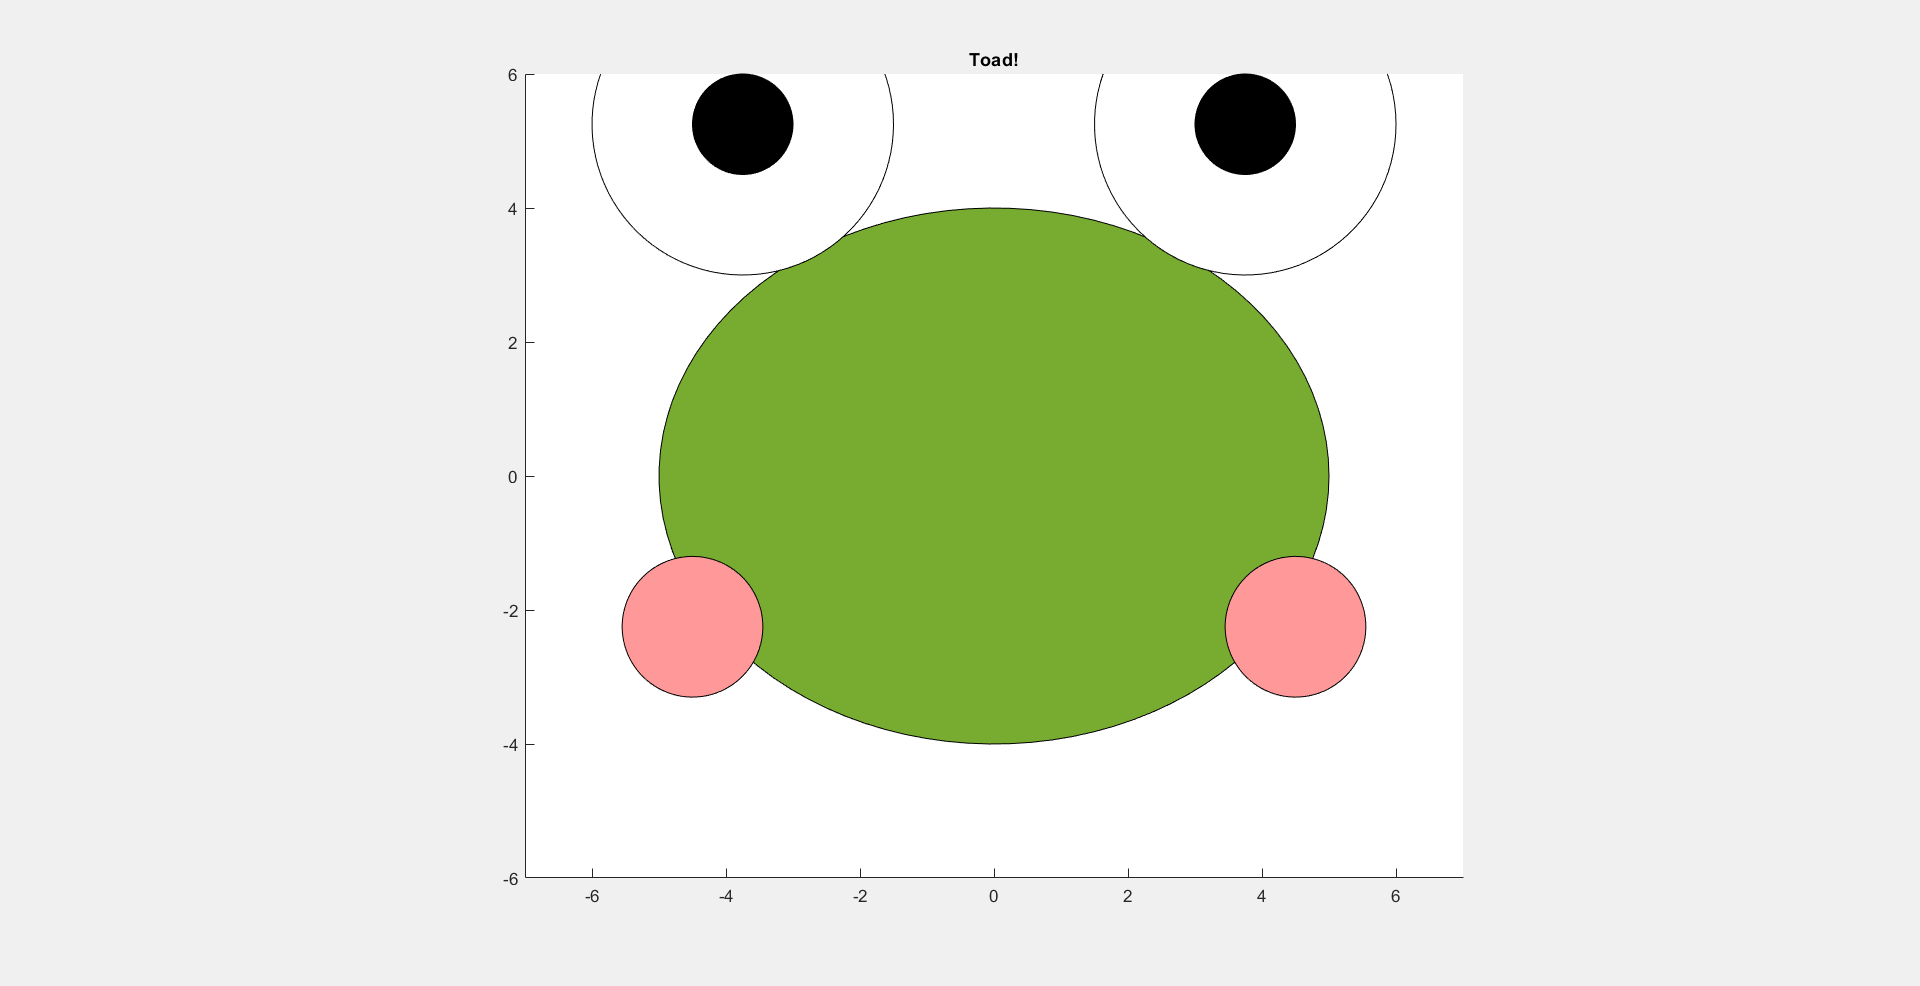

    
    % Pause for the zoom effect
    pause(zoom_duration / steps);
zoom_duration = 0.5; % Duration for zoom effect
steps = 20; % Number of steps for zooming
scale_factor = 1.5; % Scale factor for zoom

% Zoom in the eyes, pupils, and blush
for s = 1:steps
    current_scale = 1 + (scale_factor - 1) * (s / steps);
    
    % Update eye positions
    x_eye_left_zoomed = current_scale * (1.5 * cos(t) - 2.5);  
    y_eye_left_zoomed = current_scale * (1.5 * sin(t) + 3.5);  
    x_eye_right_zoomed = current_scale * (1.5 * cos(t) + 2.5);  
    y_eye_right_zoomed = current_scale * (1.5 * sin(t) + 3.5);  
    
    % Update pupil positions (zooming in)
    x_pupil_left_zoomed = current_scale * (0.5 * cos(t) - 2.5);  
    y_pupil_left_zoomed = current_scale * (0.5 * sin(t) + 3.5);  
    x_pupil_right_zoomed = current_scale * (0.5 * cos(t) + 2.5);  
    y_pupil_right_zoomed = current_scale * (0.5 * sin(t) + 3.5);  

    % Update blush positions (zooming in)
    x_blush_left_zoomed = current_scale * (0.7 * cos(t) - 3);  
    y_blush_left_zoomed = current_scale * (0.7 * sin(t) - 1.5);  
    x_blush_right_zoomed = current_scale * (0.7 * cos(t) + 3);  
    y_blush_right_zoomed = current_scale * (0.7 * sin(t) - 1.5);  

    % Clear and redraw the frog with zoomed eyes, pupils, and blush
    clf; % Clear the figure
    hold on;  
    fill(x_head, y_head, [0.4660 0.6740 0.1880]);  
    fill(x_eye_left_zoomed, y_eye_left_zoomed, [1 1 1]);  
    fill(x_eye_right_zoomed, y_eye_right_zoomed, [1 1 1]);  
    fill(x_pupil_left_zoomed, y_pupil_left_zoomed, [0 0 0]);  
    fill(x_pupil_right_zoomed, y_pupil_right_zoomed, [0 0 0]);  
    fill(x_blush_left_zoomed, y_blush_left_zoomed, [1 0.6 0.6]);  
    fill(x_blush_right_zoomed, y_blush_right_zoomed, [1 0.6 0.6]);  

    % Plot settings
    axis equal;
    axis([-7 7 -6 6]);
    title('Toad!');
    
    % Pause for the zoom effect
    pause(zoom_duration / steps);
end